# EVALUATENET

Evaluate the network programmatically.

## Create and train the network

createNNet

## Predict activity based on model

This returns a score, and maximum score is the class

scoreTest = net(X(:,tr.testInd));
[~,yPred] = max(scoreTest);
yPred = yPred'; % row -> column

## Evaluate classification with confusion matrix

HDtest = heartdataAll.HeartDisease(tr.testInd);
yP = categorical(yPred,1:2,["false", "true"]);

Converting to categorical first allows specification of the possible classes, so yP will have the same dimensions are yT, even if not all the classes are predicted.

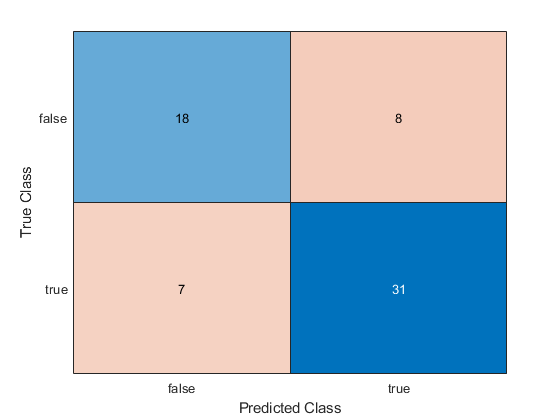

confusionchart(HDtest,yP);

## Determine error on the test set

testErr = 100*nnz(yP ~= HDtest)/length(HDtest)

testErr = 23.4375